## Initial setup

% clear memory, figures, command window, output numbers in standard notation
clear all;
close all;
clc;
format long g;

## User Inputs

prn = 12;

preciseFile = 'Ephemeris Files of Jan 08th, 2022/igs21916.sp3';
brdcFile = 'Ephemeris Files of Jan 08th, 2022/brdc0080.22n';
almanacFile = 'Ephemeris Files of Jan 08th, 2022/Almanac-SatPos-PRN12.txt';
urPredFile = 'Ephemeris Files of Jan 08th, 2022/igu21916_00.sp3';
urObsFile = 'Ephemeris Files of Jan 08th, 2022/igu21920_00.sp3';

## Task1 - Sky plot of satellite

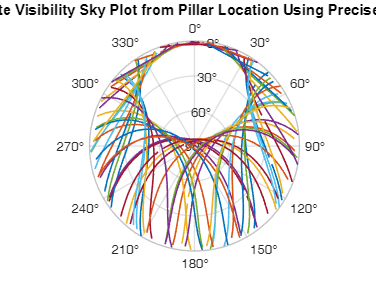

% Read the sp3 file  
precisedata_0 = readSP3(preciseFile);
precisedata = NaN(96,4);
for j = 1:96
    % Time of transmission
    time_of_transmission = 518400 + (j - 1) * 900;

    % Iterate through urPreddata_0 and filter rows
    for i = 1:size(precisedata_0, 1)
        % Check if the first number is 12 and third number equals time_of_transmission
        if precisedata_0(i, 1) == 12 && precisedata_0(i, 3) == time_of_transmission
            % Store columns 3, 4, 5, and 6 in urPreddata
            precisedata(j, :) = [precisedata_0(i, 3), precisedata_0(i, 4) * 10^3, precisedata_0(i, 5) * 10^3, precisedata_0(i, 6) * 10^3];
        end
    end
end

% get the receiver position
receiverdata = [-1641900.798, -3664874.335, 4939969.355, 51.07942678, -114.13286260, 1116.588];
[x_r, y_r, z_r, phi, lambda, h] = deal(receiverdata(1), receiverdata(2), receiverdata(3), receiverdata(4), receiverdata(5), receiverdata(6));
R = [-sind(lambda), cosd(lambda), 0; -sind(phi)*cosd(lambda), -sind(phi)*sind(lambda), cosd(phi); cosd(phi)*cosd(lambda), cosd(phi)*sind(lambda), sind(phi)];

% Initialize figure for plotting
precisedata_v = [];
figure;
ax = polaraxes; % Define polar axes
hold on;

for sat_prn = 1:32
    % Find the data for the current satellite
    idx = find(precisedata_0(:,1) == sat_prn);
    PRN = precisedata_0(idx, :);  % All data for the current satellite
    AE = zeros(length(PRN), 2);   % Initialize azimuth and elevation arrays

    for iepoch = 1:length(PRN)
        % Calculate the vector from the receiver to the satellite (in meters)
        Vector = (PRN(iepoch, 4:6) * 10^3) - [x_r, y_r, z_r];  % Convert satellite position to relative receiver position

        % Transform the vector to ENU coordinates
        ENU = R * Vector';

        % Compute azimuth and elevation
        Azi = atan2d(ENU(1), ENU(2));  % Azimuth in degrees
        Ele = asind(ENU(3) / norm(ENU));  % Elevation in degrees

        % Only keep satellites with elevation greater than 0
        if Ele > 0
            precisedata_v = [precisedata_v; PRN(iepoch,:)];
            AE(iepoch, :) = [Azi, Ele];  % Store the data where elevation > 0
        else
            AE(iepoch, :) = [NaN, NaN];  % Set NaN for data points that are below the horizon
        end
    end

    % Convert azimuth to radians and adjust elevation for plotting
    azimuth_rad = deg2rad(AE(:,1));  % Convert azimuth from degrees to radians
    elevation_scaled = 90 - AE(:,2);  % Adjust elevation for plotting

    % Plot the data on the polar axes
    polarplot(ax, azimuth_rad, elevation_scaled, '-', 'LineWidth', 1.2);
end

hold off;
% Finalize the plot
ax.ThetaZeroLocation = 'top';
ax.ThetaDir = 'clockwise';
ax.RTick = [0 30 60 90];
ax.RTickLabel = {'90°', '60°', '30°', '0°'};
title(ax, '24-Hour Satellite Visibility Sky Plot from Pillar Location Using Precise Ephemeris Data');


% DOPs computation
time_unique = unique(precisedata_v(:, 3));  % Unique epochs
DOP_data = time_unique;  % Store DOP values

for t = 1:size(time_unique)
    idx = find(precisedata_v(:,3) == time_unique(t));
    satXYZ = precisedata_v(idx, :);
    A = zeros(length(satXYZ), 4);

    for n = 1:length(satXYZ)
        % Satellite position in meters
        Xs = satXYZ(n, 4) * 10^3;
        Ys = satXYZ(n, 5) * 10^3;
        Zs = satXYZ(n, 6) * 10^3;

        % Compute geometric distance
        dist = sqrt((Xs - x_r)^2 + (Ys - y_r)^2 + (Zs - z_r)^2);

        % Partial derivatives
        A(n, 1) = (x_r - Xs) / dist;
        A(n, 2) = (y_r - Ys) / dist;
        A(n, 3) = (z_r - Zs) / dist;
        A(n, 4) = -1;
    end

    % Compute the geometry matrix and DOP values
    Qecef = (A' * A)^-1;
    Qenu = R * Qecef(1:3, 1:3) * R';

    NDOP = sqrt(Qenu(1, 1));
    EDOP = sqrt(Qenu(2, 2));
    HDOP = sqrt(trace(Qenu(1:2, 1:2)));  % Horizontal DOP
    VDOP = sqrt(Qenu(3, 3));
    NOVS = length(satXYZ);  % Number of visible satellites

    % Store DOP values
    DOP_data(t,2:6) = [NDOP, EDOP, HDOP, VDOP, NOVS];
end

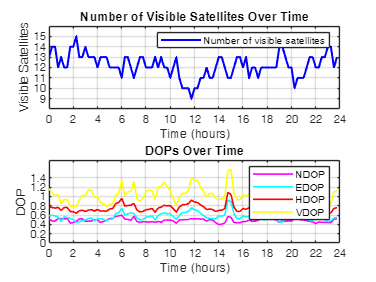


% Extract time (assuming it's in seconds) and convert to hours
time_hours = (DOP_data(:,1) - min(DOP_data(:,1))) / 3600;  % Convert to hours
num_satellites = DOP_data(:,6);

% Extract DOP values
NDOP = DOP_data(:,2);
EDOP = DOP_data(:,3);
HDOP = DOP_data(:,4);
VDOP = DOP_data(:,5);

% Create a figure with two subplots
figure;

% First subplot: Number of visible satellites
subplot(2,1,1);
plot(time_hours, num_satellites, '-b', 'LineWidth', 1.5);
xlabel('Time (hours)');
ylabel('Visible Satellites');
title('Number of Visible Satellites Over Time');
grid on;
legend('Number of visible satellites', 'Location', 'northeast');

% Adjust x-axis (set proper spacing)
xticks(0:2:24); % Tick every 2 hours
xlim([0 24]);   % Limit x-axis to 24 hours

% Adjust y-axis (ensure clear satellite count spacing)
yticks(min(num_satellites):1:max(num_satellites));
ylim([min(num_satellites)-1, max(num_satellites)+1]); % Add buffer space

% Second subplot: DOP values over time
subplot(2,1,2);
plot(time_hours, NDOP, '-m', 'LineWidth', 1.2); hold on;
plot(time_hours, EDOP, '-c', 'LineWidth', 1.2);
plot(time_hours, HDOP, '-r', 'LineWidth', 1.2);
plot(time_hours, VDOP, '-y', 'LineWidth', 1.2);
xlabel('Time (hours)');
ylabel('DOP');
title('DOPs Over Time');
grid on;
legend('NDOP', 'EDOP', 'HDOP', 'VDOP', 'Location', 'northeast');

% Adjust x-axis for DOP plot
xticks(0:2:24); % Same 2-hour intervals for consistency
xlim([0 24]);

% Adjust y-axis for DOP values
yticks(0:0.2:max([NDOP; EDOP; HDOP; VDOP])); % Adjust tick spacing dynamically
ylim([0, max([NDOP; EDOP; HDOP; VDOP]) + 0.2]); % Ensure space above max values
hold off;

% Add figure caption
annotation('textbox', [0.5, 0.02, 0, 0], 'String', 'FIGURE 3', ...
    'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'EdgeColor', 'none');

## Task2 - Satellite Position Computations

% Read .22n
fileID = fopen(brdcFile, 'r');

% to store every line
brdcdata = {};

% read data until 9th
for i = 1:8
    line = fgetl(fileID);
end

% extract data from 9th
lineNum = 1;
while ~feof(fileID)
    line = fgetl(fileID);
    line = strrep(line, 'D', 'E');
    tokens = str2double(regexp(line, '([-+]?\d+\.\d+E[+-]\d+|[-+]?\d+(\.\d+)?)', 'match'));

    dataMatrix = tokens;
    brdcdata{lineNum} = dataMatrix;

    lineNum = lineNum + 1;
end

% close file
fclose(fileID);

% to store the consolidated data
brdcData = {};

% loop through the brdcdata array
index = 1;
while index <= numel(brdcdata)
    % Find the 1x10 cell (this is the start of a new block)
    if numel(brdcdata{index}) == 10
        % Create a temporary array to store the current block's data
        currentBlock = NaN(8, 10);  % Initialize 8 rows, 10 columns
        
        % Fill the first row with the 1x10 data
        currentBlock(1, :) = brdcdata{index};  % First row is 1x10 cell

        % Loop through the next 7 rows of data (each with 1x4 cells)
        for i = 1:7
            index = index + 1;  % Move to the next row
            if index <= numel(brdcdata)
                % Fill the current row (1x4 data) into the currentBlock matrix
                currentBlock(i + 1, 1) = brdcdata{index}(1);  % First element of 1x4 data
                currentBlock(i + 1, 2) = brdcdata{index}(2);  % Second element of 1x4 data
                currentBlock(i + 1, 3) = brdcdata{index}(3);  % Third element of 1x4 data
                currentBlock(i + 1, 4) = brdcdata{index}(4);  % Fourth element of 1x4 data
            end
        end
        
        % Add the reorganized data block as a new row in newBrdcData
        brdcData{end+1} = currentBlock;
    end
    index = index + 1;  % Move to the next 1x10 cell
end

% Extract PRN 12 Data
prn12_data = {};  % Empty cell array to store PRN 12 data

for i = 1:length(brdcData)
    % Convert first element of each block (PRN) to a number
    PRN = brdcData{i}(1, 1);
    
    % If PRN matches 12, store it
    if PRN == 12
        prn12_data{end+1} = brdcData{i};
    end
end

% Using the best and the first broadcast ephemeris record to do the
% computation
brdcbest = NaN(96,4);
brdc24hr = NaN(96,4);

for j = 1:96
    % Time of transmission
    time_of_transmission = 518400 + (j-1) * 900;
    timediff = zeros(1,13);
    
    % Find the nearest Toe for best ephemeris
    for i = 1:13
        Toe = prn12_data{i}(4,1);
        timediff(i) = abs(Toe - time_of_transmission);
    end
    
    % Find minimum timediff for best ephemeris
    [~, min_index] = min(timediff);

    % Extract the closest ephemeris for both brdcbest and brdc24hr
    closest_ephemeris = prn12_data{min_index};
    ephemeris_24hr = prn12_data{1};  % Use the first ephemeris for 24hr

    % Calculate positions for brdcbest and brdc24hr
    [x_k_best, y_k_best, z_k_best] = compute_satellite_position(closest_ephemeris, time_of_transmission);
    [x_k_24hr, y_k_24hr, z_k_24hr] = compute_satellite_position(ephemeris_24hr, time_of_transmission);

    % Store the results in the respective matrices
    brdcbest(j, :) = [time_of_transmission, x_k_best, y_k_best, z_k_best];
    brdc24hr(j, :) = [time_of_transmission, x_k_24hr, y_k_24hr, z_k_24hr];
end

% Save brdcbest matrix to brdcbest.xyz
writematrix(brdcbest, 'brdcbest.xyz', 'Delimiter', '\t', 'FileType', 'text');

% Save brdc24hr matrix to brdc24hr.xyz
writematrix(brdc24hr, 'brdc24hr.xyz', 'Delimiter', '\t', 'FileType', 'text');

## Task3 - Error Computations

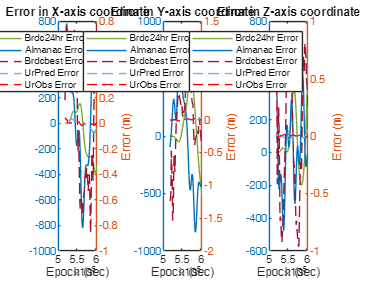

% Read the position using the almanac parameters
almanacdata = readmatrix(almanacFile);

% Read the position using the predicted and observed ephemeris data
urPreddata_0 = readSP3(urPredFile);
urObsdata_0 = readSP3(urObsFile);

% Extract PRN12 data from the predicted and observed data
urPreddata = NaN(96,4);
urObsdata = NaN(96,4);

for j = 1:96
    % Time of transmission
    time_of_transmission = 518400 + (j - 1) * 900;
    
    % Iterate through urPreddata_0 and filter rows
    for i = 1:size(urPreddata_0, 1)
        % Check if the first number is 12 and third number equals time_of_transmission
        if urPreddata_0(i, 1) == 12 && urPreddata_0(i, 3) == time_of_transmission
            % Store columns 3, 4, 5, and 6 in urPreddata
            urPreddata(j, :) = [urPreddata_0(i, 3), urPreddata_0(i, 4) * 10^3, urPreddata_0(i, 5) * 10^3, urPreddata_0(i, 6) * 10^3];
        end
    end
end

for j = 1:96
    % Time of transmission
    time_of_transmission = 518400 + (j - 1) * 900;

    % Iterate through urPreddata_0 and filter rows
    for i = 1:size(urObsdata_0, 1)
        % Check if the first number is 12 and third number equals time_of_transmission
        if urObsdata_0(i, 1) == 12 && urObsdata_0(i, 3) == time_of_transmission
            % Store columns 3, 4, 5, and 6 in urPreddata
            urObsdata(j, :) = [urObsdata_0(i, 3), urObsdata_0(i, 4) * 10^3, urObsdata_0(i, 5) * 10^3, urObsdata_0(i, 6) * 10^3];
        end
    end
end

% Error computation
brdcbest_error = brdcbest - precisedata;
brdcbest_error(:, 1) = brdcbest(:, 1);

brdc24hr_error = brdc24hr - precisedata;
brdc24hr_error(:, 1) = brdc24hr(:, 1);

almanac_error = almanacdata - precisedata;
almanac_error(:, 1) = almanacdata(:, 1);

urPred_error = urPreddata - precisedata;
urPred_error(:, 1) = urPreddata(:, 1);

urObs_error = urObsdata - precisedata;
urObs_error(:, 1) = urObsdata(:, 1);

% Plot errors as a function of time
figure;

% Subplot 1: Error in X-axis coordinate
subplot(1,3,1);
yyaxis left;
plot(brdcbest_error(:, 1), brdc24hr_error(:, 2), 'Color', '#77AC30', 'LineStyle', '-'); % solid line
hold on;
plot(brdcbest_error(:, 1), almanac_error(:, 2), 'Color', '#0072BD', 'LineStyle', '-'); % solid line
yyaxis right;
plot(brdcbest_error(:, 1), brdcbest_error(:, 2), 'Color', '#A2142F', 'LineStyle', '--'); % dashed line
plot(brdcbest_error(:, 1), urPred_error(:, 2), 'Color', '#4DBEEE', 'LineStyle', '--'); % dashed line
plot(brdcbest_error(:, 1), urObs_error(:, 2), 'r', 'LineStyle', '--'); % dashed line
legend('Brdc24hr Error', 'Almanac Error','Brdcbest Error', 'UrPred Error', 'UrObs Error');
xlabel('Epoch (sec)');
ylabel('Error (m)');
title('Error in X-axis coordinate');

% Subplot 2: Error in Y-axis coordinate
subplot(1,3,2);
yyaxis left;
plot(brdcbest_error(:, 1), brdc24hr_error(:, 3), 'Color', '#77AC30', 'LineStyle', '-'); % solid line
hold on;
plot(brdcbest_error(:, 1), almanac_error(:, 3), 'Color', '#0072BD', 'LineStyle', '-'); % solid line
yyaxis right;
plot(brdcbest_error(:, 1), brdcbest_error(:, 3), 'Color', '#A2142F', 'LineStyle', '--'); % dashed line
plot(brdcbest_error(:, 1), urPred_error(:, 3), 'Color', '#4DBEEE', 'LineStyle', '--'); % dashed line
plot(brdcbest_error(:, 1), urObs_error(:, 3), 'r', 'LineStyle', '--'); % dashed line
legend('Brdc24hr Error', 'Almanac Error','Brdcbest Error', 'UrPred Error', 'UrObs Error');
xlabel('Epoch (sec)');
ylabel('Error (m)');
title('Error in Y-axis coordinate');

% Subplot 3: Error in Z-axis coordinate
subplot(1,3,3);
yyaxis left;
plot(brdcbest_error(:, 1), brdc24hr_error(:, 4), 'Color', '#77AC30', 'LineStyle', '-'); % solid line
hold on;
plot(brdcbest_error(:, 1), almanac_error(:, 4), 'Color', '#0072BD', 'LineStyle', '-'); % solid line
yyaxis right;
plot(brdcbest_error(:, 1), brdcbest_error(:, 4), 'Color', '#A2142F', 'LineStyle', '--'); % dashed line
plot(brdcbest_error(:, 1), urPred_error(:, 4), 'Color', '#4DBEEE', 'LineStyle', '--'); % dashed line
plot(brdcbest_error(:, 1), urObs_error(:, 4), 'r', 'LineStyle', '--'); % dashed line
legend('Brdc24hr Error', 'Almanac Error','Brdcbest Error', 'UrPred Error', 'UrObs Error');
xlabel('Epoch (sec)');
ylabel('Error (m)');
title('Error in Z-axis coordinate');

## Task4 - Error Analysis

% For broadcast best data
brdcbest_max_error = max(abs(brdcbest_error(:, 2:4)));
brdcbest_mean_error = mean(brdcbest_error(:, 2:4));
brdcbest_std_error = std(brdcbest_error(:, 2:4));
brdcbest_rmse_error = sqrt(mean(brdcbest_error(:, 2:4).^2));
fprintf('brdcbest max error: X = %f, Y = %f, Z = %f\n', brdcbest_max_error(1), brdcbest_max_error(2), brdcbest_max_error(3));

brdcbest max error: X = 0.862100, Y = 1.536188, Z = 0.962183


fprintf('brdcbest mean error: X = %f, Y = %f, Z = %f\n', brdcbest_mean_error(1), brdcbest_mean_error(2), brdcbest_mean_error(3));

brdcbest mean error: X = 0.017590, Y = -0.019755, Z = -0.022253


fprintf('brdcbest standard deviation error: X = %f, Y = %f, Z = %f\n', brdcbest_std_error(1), brdcbest_std_error(2), brdcbest_std_error(3));

brdcbest standard deviation error: X = 0.515654, Y = 0.580929, Z = 0.580267


fprintf('brdcbest rmse error: X = %f, Y = %f, Z = %f\n', brdcbest_rmse_error(1), brdcbest_rmse_error(2), brdcbest_rmse_error(3));

brdcbest rmse error: X = 0.513262, Y = 0.578233, Z = 0.577666



% For broadcast 24-hour data
brdc24hr_max_error = max(abs(brdc24hr_error(:, 2:4)));
brdc24hr_mean_error = mean(brdc24hr_error(:, 2:4));
brdc24hr_std_error = std(brdc24hr_error(:, 2:4));
brdc24hr_rmse_error = sqrt(mean(brdc24hr_error(:, 2:4).^2));
fprintf('brdc24hr max error: X = %f, Y = %f, Z = %f\n', brdc24hr_max_error(1), brdc24hr_max_error(2), brdc24hr_max_error(3));

brdc24hr max error: X = 392.286587, Y = 554.240593, Z = 539.183704


fprintf('brdc24hr mean error: X = %f, Y = %f, Z = %f\n', brdc24hr_mean_error(1), brdc24hr_mean_error(2), brdc24hr_mean_error(3));

brdc24hr mean error: X = -79.013671, Y = 84.170106, Z = 67.907623


fprintf('brdc24hr standard deviation error: X = %f, Y = %f, Z = %f\n', brdc24hr_std_error(1), brdc24hr_std_error(2), brdc24hr_std_error(3));

brdc24hr standard deviation error: X = 178.621237, Y = 262.666576, Z = 172.849670


fprintf('brdc24hr rmse error: X = %f, Y = %f, Z = %f\n', brdc24hr_rmse_error(1), brdc24hr_rmse_error(2), brdc24hr_rmse_error(3));

brdc24hr rmse error: X = 194.464283, Y = 274.517126, Z = 184.870860



% For almanac data
almanac_max_error = max(abs(almanac_error(:, 2:4)));
almanac_mean_error = mean(almanac_error(:, 2:4));
almanac_std_error = std(almanac_error(:, 2:4));
almanac_rmse_error = sqrt(mean(almanac_error(:, 2:4).^2));
fprintf('almanac max error: X = %f, Y = %f, Z = %f\n', almanac_max_error(1), almanac_max_error(2), almanac_max_error(3));

almanac max error: X = 819.490937, Y = 862.284206, Z = 639.797054


fprintf('almanac mean error: X = %f, Y = %f, Z = %f\n', almanac_mean_error(1), almanac_mean_error(2), almanac_mean_error(3));

almanac mean error: X = 61.233320, Y = -32.863392, Z = 12.922113


fprintf('almanac standard deviation error: X = %f, Y = %f, Z = %f\n', almanac_std_error(1), almanac_std_error(2), almanac_std_error(3));

almanac standard deviation error: X = 434.683737, Y = 457.601733, Z = 243.716124


fprintf('almanac rmse error: X = %f, Y = %f, Z = %f\n', almanac_rmse_error(1), almanac_rmse_error(2), almanac_rmse_error(3));

almanac rmse error: X = 436.727881, Y = 456.396872, Z = 242.787573




% For the Predicted data
urPred_max_error = max(abs(urPred_error(:, 2:4)));
urPred_mean_error = mean(urPred_error(:, 2:4));
urPred_std_error = std(urPred_error(:, 2:4));
urPred_rmse_error = sqrt(mean(urPred_error(:, 2:4).^2));
fprintf('urPred max error: X = %f, Y = %f, Z = %f\n', urPred_max_error(1), urPred_max_error(2), urPred_max_error(3));

urPred max error: X = 0.077000, Y = 0.044000, Z = 0.054000


fprintf('urPred mean error: X = %f, Y = %f, Z = %f\n', urPred_mean_error(1), urPred_mean_error(2), urPred_mean_error(3));

urPred mean error: X = -0.007219, Y = 0.005146, Z = -0.005698


fprintf('urPred standard deviation error: X = %f, Y = %f, Z = %f\n', urPred_std_error(1), urPred_std_error(2), urPred_std_error(3));

urPred standard deviation error: X = 0.033572, Y = 0.019894, Z = 0.018308


fprintf('urPred rmse error: X = %f, Y = %f, Z = %f\n', urPred_rmse_error(1), urPred_rmse_error(2), urPred_rmse_error(3));

urPred rmse error: X = 0.034168, Y = 0.020448, Z = 0.019083



% For the Observed data
urObs_max_error = max(abs(urObs_error(:, 2:4)));
urObs_mean_error = mean(urObs_error(:, 2:4));
urObs_std_error = std(urObs_error(:, 2:4));
urObs_rmse_error = sqrt(mean(urObs_error(:, 2:4).^2));
fprintf('urObs max error: X = %f, Y = %f, Z = %f\n', urObs_max_error(1), urObs_max_error(2), urObs_max_error(3));

urObs max error: X = 0.043000, Y = 0.017000, Z = 0.013000


fprintf('urObs mean error: X = %f, Y = %f, Z = %f\n', urObs_mean_error(1), urObs_mean_error(2), urObs_mean_error(3));

urObs mean error: X = 0.001531, Y = -0.000490, Z = 0.000187


fprintf('urObs standard deviation error: X = %f, Y = %f, Z = %f\n', urObs_std_error(1), urObs_std_error(2), urObs_std_error(3));

urObs standard deviation error: X = 0.011940, Y = 0.007721, Z = 0.006823


fprintf('urObs rmse error: X = %f, Y = %f, Z = %f\n', urObs_rmse_error(1), urObs_rmse_error(2), urObs_rmse_error(3));

urObs rmse error: X = 0.011976, Y = 0.007697, Z = 0.006790
